**制御対象の伝達関数　P(s) = K/(s-p1)(s-p2)**

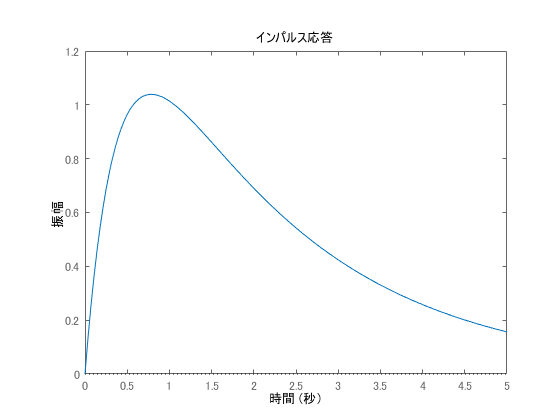

pole1 =-2.6;
pole2 = -0.5;
amp1 = 4;

plant1 = amp1*tf(1,[1 -pole1-pole2 pole1*pole2]);

impulse(plant1,5)

図１：制御対象のインパルス応答

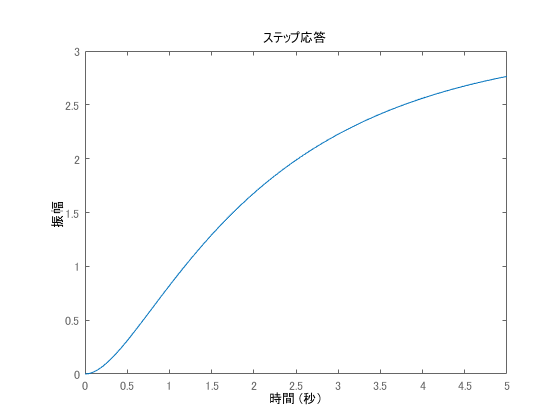

step(plant1,5);

図２：制御対象のステップ応答

**PIDコントローラの伝達関数　C(s) = Kp + Kd s/(eps s+1) + Ki /s (ただし，eps = 0.01)**

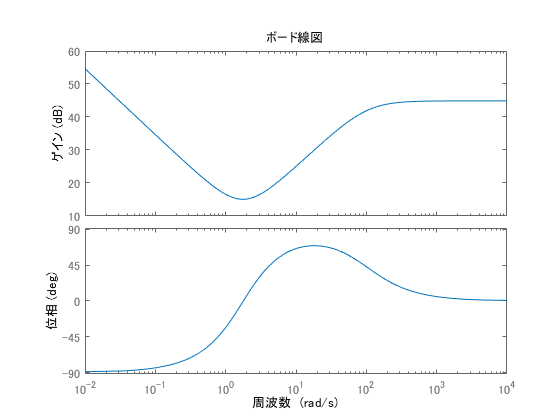

kp = 5.6;
kd = 1.7;
ki = 5.4;

contr1 = tf([kp ki],[1 0])+tf([kd 0],[0.01 1]);
bode(contr1);

図３：PIDコントローラのボード線図

**一巡伝達関数 L(s) = P(s)C(s) のナイキスト線図**

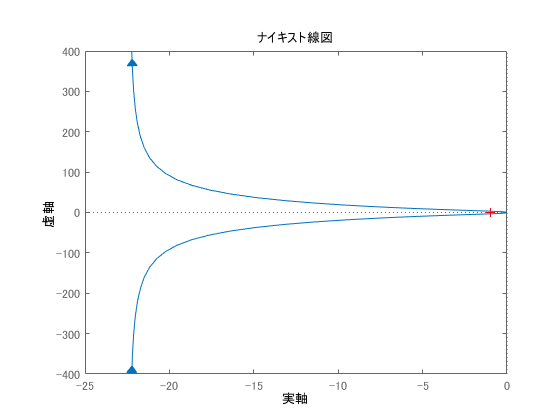

nyquist(plant1*contr1);

図４：ナイキスト線図

**閉ループ系の応答結果 T(s) = P(s)C(s)/(1+P(s)C(s)), T(s)のステップ応答**

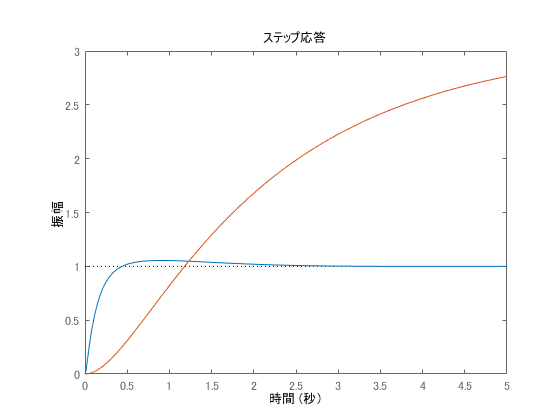

T1 = feedback(plant1*contr1,1,-1);
step(T1,plant1,5);

図５：フィードバック系のステップ応答（赤は制御対象のステップ応答）